# Unsupervised Learning In-Class Practice: Answer Key

## Loading and examining the data

% Load the dataset
tcga = readtable('cancer_RNAseq_data.xlsx');

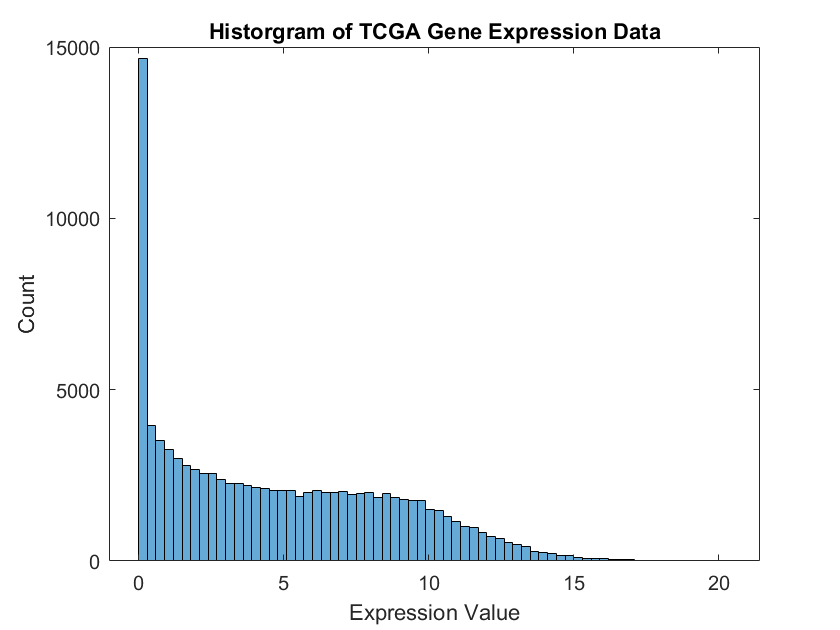

% Create a variable for patient IDs
patient_ID = tcga.Patient;
% Create a variable for gene names
genes = tcga.Properties.VariableNames(2:end);
% Create a variable for gene expression data
tcga_data = table2array(tcga(:,2:end));

% Histogram of data
histogram(tcga_data)
xlabel('Expression Value')
ylabel('Count')
title('Historgram of TCGA Gene Expression Data')

Answer: All values are positive. 

## Visualizing data using HC

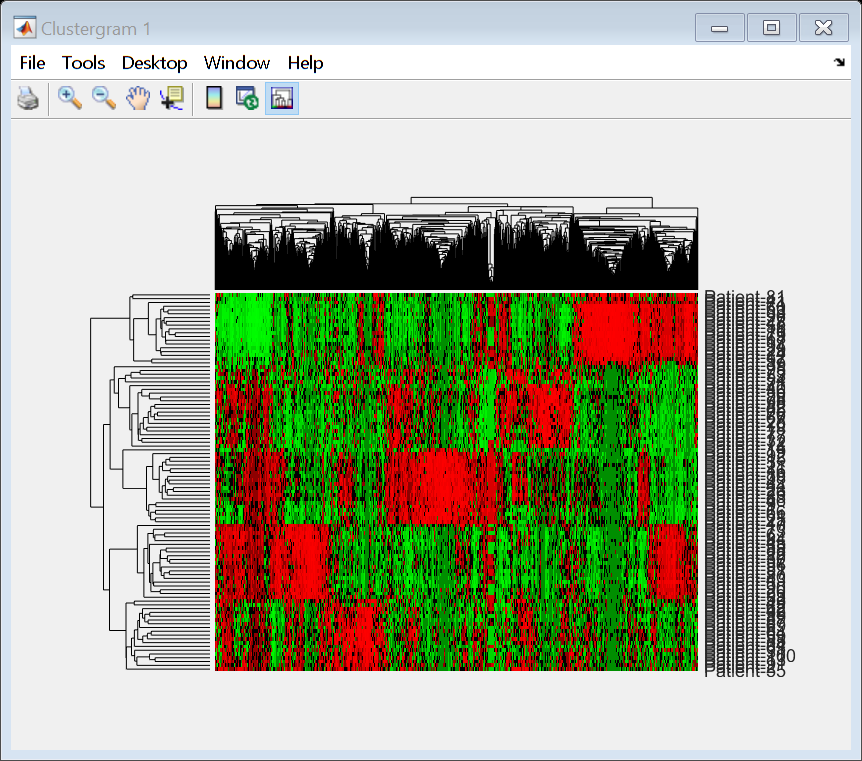

% Create clustergram (label rows, label columns, and standardize by
% columns)
tcga_cg = clustergram(tcga_data,...
    'RowLabels',patient_ID,...
    'ColumnLabels',genes,...
    'Standardize','column');

Answer: One example is KLK2 (Kallikrein Related Peptidase 2). Down-regulation of this gene is implicated with prostate cancer (prostate adenocarcinoma).

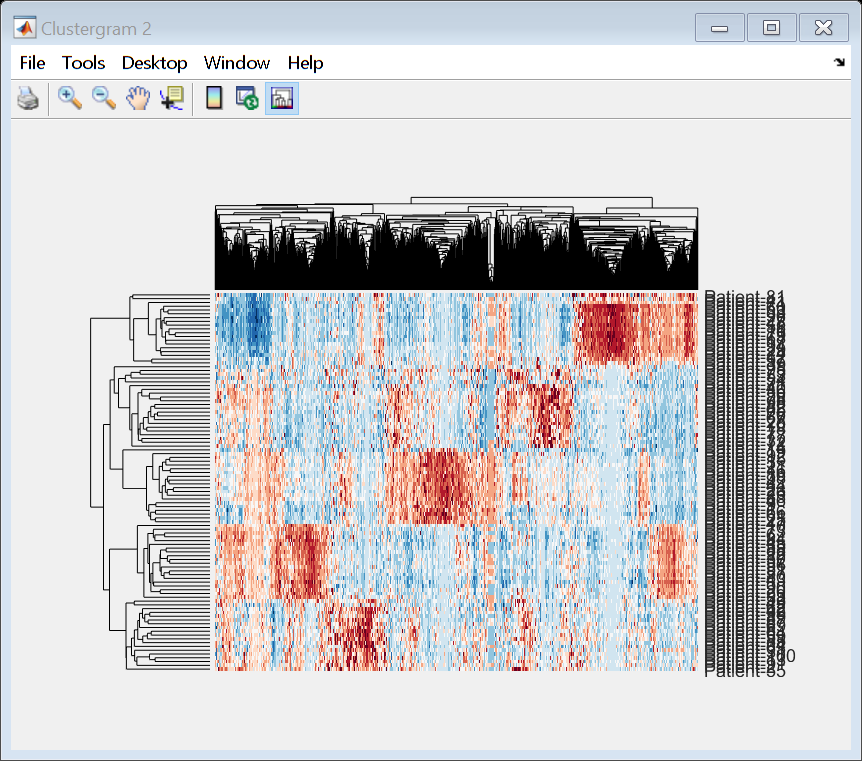

% Clustergram with redbluecmap
tcga_cg_rbc = clustergram(tcga_data,...
    'RowLabels',patient_ID,...
    'ColumnLabels',genes,...
    'Standardize','column',...
    'Colormap',redbluecmap);

## Determining best k value using KMC

% Create a vector of k values ranging from 2 to 10
k_values = 2:10;

% For-loop to calculate the silhouette statistic for different k values
n = length(k_values);       % number of k values
s_statistic = zeros(n,1);   % variable to store silhouette statistic values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    [idx,~] = kmeans(tcga_data,k_values(i));
    % Use the silhouette function to calculate silhouette values
    s = silhouette(tcga_data,idx);
    % Calculate a weight value proportional to positive silhouette values
    weight = sum(s > 0)/length(s);
    % Calculate the silhouette statistic by multiplying the weight with the
    % mean of silhouette values and store this to s_statistic
    s_statistic(i) = weight*mean(s);
end
max(s_statistic)

ans = 0.5658

find(s_statistic==max(s_statistic))+1

ans = 5

Answer: The max silhouette statistic is equal to 0.5658, and this corresponds with k = 5.

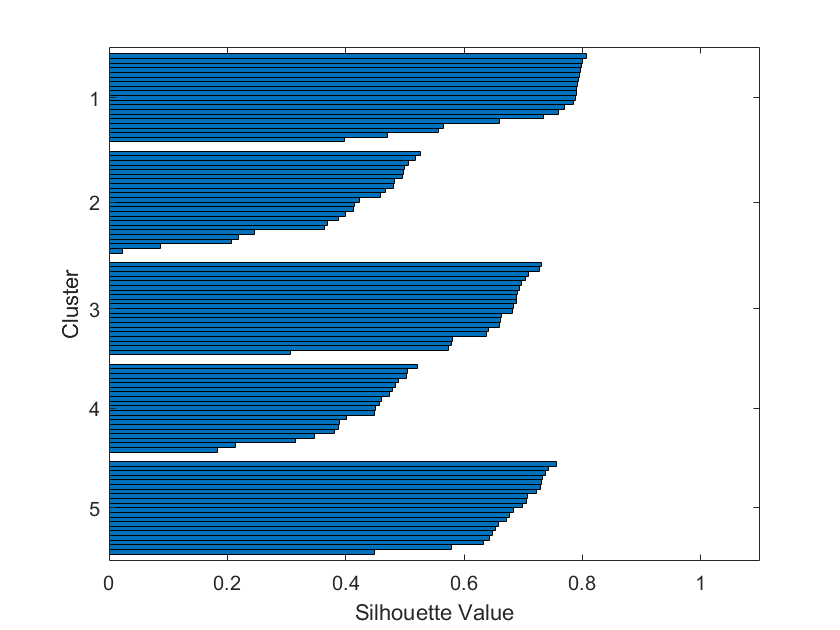

% Silhouette plot based on best k value
[idx,~] = kmeans(tcga_data,5);
silhouette(tcga_data,idx)

## Re-visualizing data using PCA

% Apply PCA to the gene expression data (use patient IDs for labeling)
mapcaplot(tcga_data,patient_ID)

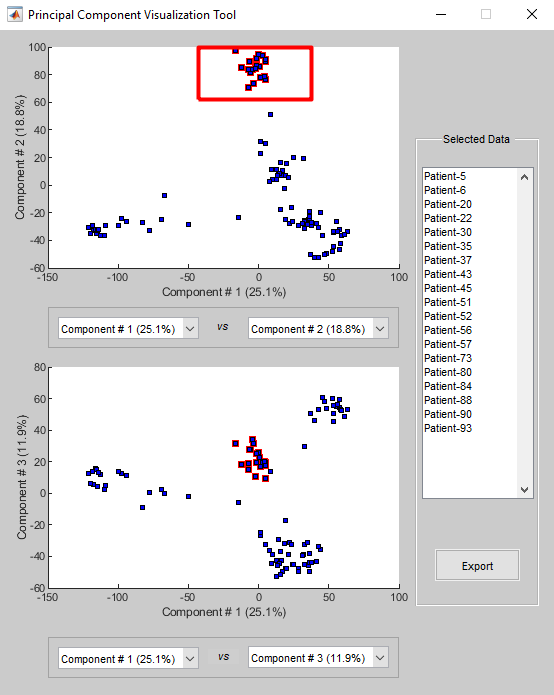

Answer: We can see 4-5 distinct clusters. PC1 and PC2 account for 43.9% of the variance. 

Activity: patient IDs for a cluster in PCA should match with a row cluster in the clustergram.

## Additional questions

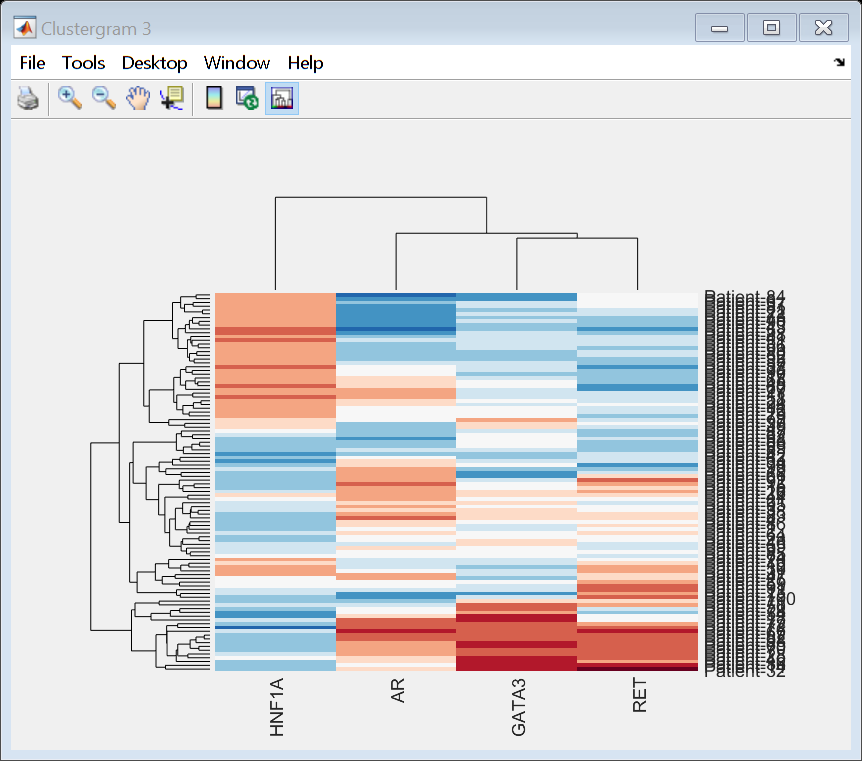

% Load the data subset
tcga_subset = readtable('cancer_RNAseq_subset.xlsx');
% Create a variable for patient IDs
patient_ID = tcga_subset.Patient;
% Create a variable for gene names
subset_genes = tcga_subset.Properties.VariableNames(2:end);
% Create a variable for gene expression data
tcga_subset_data = table2array(tcga_subset(:,2:end));

% Clustergram of data subset
tcga_subset_cg = clustergram(tcga_subset_data,...
    'RowLabels',patient_ID,...
    'ColumnLabels',subset_genes,...
    'Standardize','column',...
    'Colormap',redbluecmap);

Answer: Two cancer types associated with AR gene up-regulation are breast cancer and prostate cancer. 

Answer: The following colored patient clusters might be associated with either cancer type:

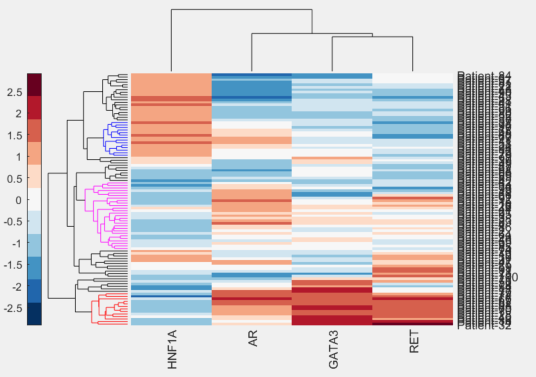

## Confirming predictions using classification data

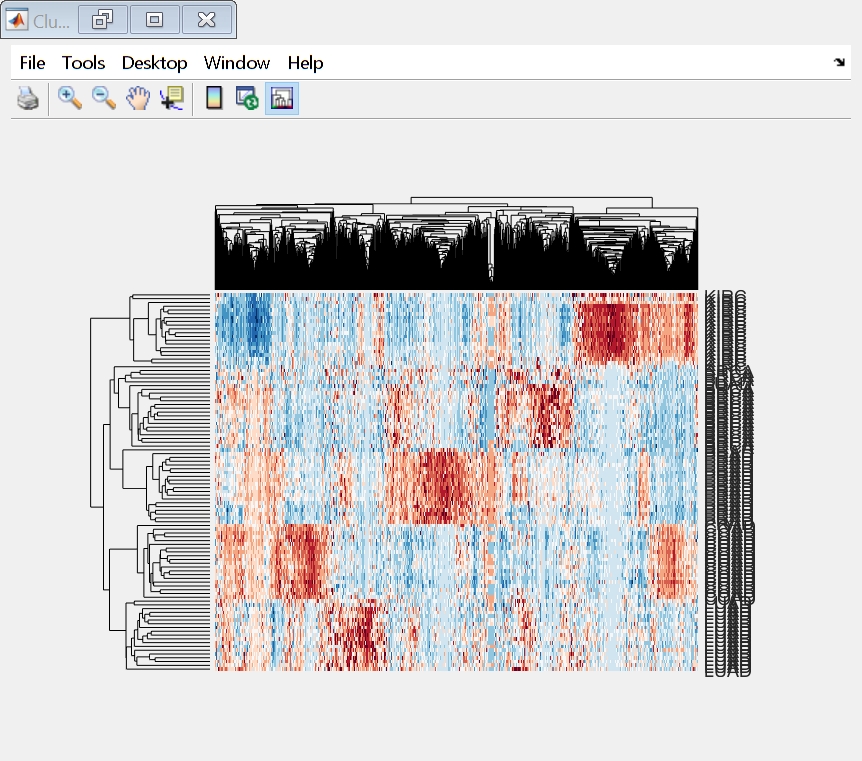

% Load the classification data
tcga_class = readtable('cancer_RNAseq_class');

% Re-generate clustergram (label rows based on classification)
tcga_cg_class = clustergram(tcga_data,...
    'RowLabels',tcga_class.Class,...
    'ColumnLabels',genes,...
    'Standardize','column',...
    'Colormap',redbluecmap);

unique(tcga_class.Class)

ans = 5×1 cell array
    {'BRCA'}
    {'COAD'}
    {'KIRC'}
    {'LUAD'}
    {'PRAD'}


Answer: 5 cancer types are represented. These are: BRCA (breast invasive carcinoma), COAD (colon adenocarcinoma), KIRC (kidney clear cell carcinoma), LUAD (lung adenocarcinoma), and PRAD (prostate adenocarcinoma). 

% Re-generate PCA plot (labels based on classification)
mapcaplot(tcga_data,tcga_class.Class)